**initialisations**

% ConversionCoef = 0; %typical 171

ConversionCoef=  140

ConversionCoef = 140

DistLimitScan =40

DistLimitScan = 50

nombredecycles=100

nombredecycles = 16

Initialisation de la connexion** Arduino et sonic Sensor**

TriggerPin = 'D12';
EchoPin = 'D13';

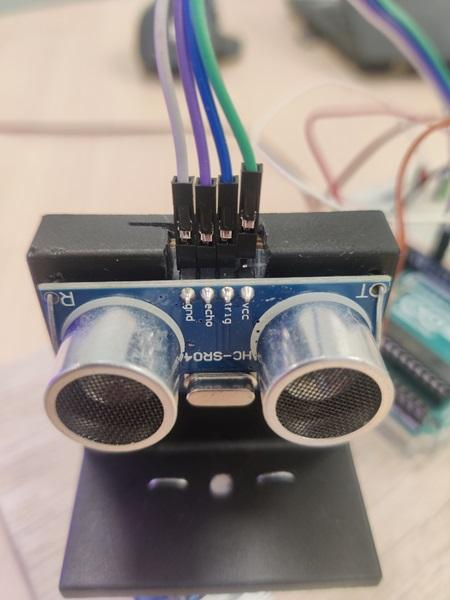

LedRED =  'D7';
LedGREEN= 'D8';
relaisDetect='D4';
PinServoM= 'D3';

a = arduino('COM3', 'Uno', 'Libraries', {'Ultrasonic', 'Servo'});

MATLAB connection to Uno at COM3 exists in your workspace. To create a new connection, clear the existing object.

configurePin(a, LedRED, 'DigitalOutput');
configurePin(a, relaisDetect, 'DigitalOutput');
configurePin(a, LedGREEN, 'DigitalOutput');

Création des objets capteur et servo

sensor = ultrasonic(a, TriggerPin, EchoPin);
servo_motor = servo(a, PinServoM);

check Leds - demarrage du programme

writeDigitalPin(a, LedGREEN, 1); 
writeDigitalPin(a, LedRED, 1); 
pause(0.80);
writeDigitalPin(a, LedGREEN, 0); 
writeDigitalPin(a, LedRED, 0); 

**Initialisation du graphique personnalisé**

figure('units', 'normalized', 'outerposition', [0 0 1 1]);
whitebg('black');
hold on;

*Dessiner les cercles de l'échelle*

th = linspace(0, pi, 1000);
R = 10:10:DistLimitScan;
for i = 1:length(R)
    x = R(i) * cos(th);
    y = R(i) * sin(th);
    plot(x, y, 'Color', [0.603922, 0.803922, 0.196078], 'LineWidth', 1);
end

*Dessiner les axes*

angle_deg = 60; % Angle en degrés
angle_rad = deg2rad(angle_deg);
AxisSmall=round(DistLimitScan*cos(angle_rad),1);

angle_deg = 30; % Angle en degrés
angle_rad = deg2rad(angle_deg);
AxisLong=round(DistLimitScan*cos(angle_rad),1);

fprintf('%15d | %13.2f |\n', AxisSmall , AxisLong);
% Dessiner les axes
%x0 = [0 100 0 0 0 0];
%x1 = [0 100 86.60 50 -50 -86.60];
%y0 = [0 0 0 0 0 0];
%y1 = [100 0 50 86.60 86.60 50]

x0 = [0 DistLimitScan 0 0 0 0];
y0 = [0 0 0 0 0 0];

x1 = [0             DistLimitScan AxisLong  AxisSmall -AxisSmall -AxisLong];
y1 = [DistLimitScan 0             AxisSmall AxisLong   AxisLong   AxisSmall];
for i = 1:length(x0)
    plot([x0(i), x1(i)], [y0(i), y1(i)], 'Color', [0.603922, 0.803922, 0.196078], 'LineWidth', 2);
     fprintf('%15d | %13.2f | %9.2f | %9.2f\n', x0(i), x1(i), y0(i), y1(i));
end


Préparer le graphique de sonar

h = gobjects(180, 1); % Pré-allocation des handles de lignes
for i = 1:180
    [x, y] = pol2cart(i * 0.0174532925, DistLimitScan);
    h(i) = plot([0, x], [0, y], 'g', 'LineWidth', 1);
end

**Rotation du moteur servo et mise à jour en temps réel**

Boucle pour "nombredecycles "occurrences

for occurrence = 1:nombredecycles

*Rotation du moteur servo*

table = zeros(180, 4);
for i = 1:180
    theta = (i - 1) / 180;
    
    writePosition(servo_motor, theta);
    dist1 = readDistance(sensor) * ConversionCoef;
    pause(0.01);
    dist2 = readDistance(sensor) * ConversionCoef;
    dist = (dist1 + dist2) / 2;
    
    % Vérifier si la distance est infinie et la limiter en cm
   if isinf(dist) || dist > DistLimitScan
       LedONLedOff(a,LedGREEN,LedRED); 
       relaisBoo(a,relaisDetect,'off');
       dist = DistLimitScan; % Limite en cm  
    else
        LedONLedOff(a,LedRED,LedGREEN);
        relaisBoo(a,relaisDetect,'on');
    end
        
    table(i, 1) = (i - 1);
    table(i, 2) = round(dist , 2);
    table(i, 3) = round(dist1, 2);
    table(i, 4) = round(dist2, 2);


    % Mise à jour du graphique en temps réel
    [x, y] = pol2cart(table(i, 1) * pi / 180, table(i, 2));
    set(h(i), 'XData', [0, x], 'YData', [0, y], 'Color', 'r', 'LineWidth', 2);
    drawnow;

%    i = i + 1;
end

*Réinitialiser la table avec des valeurs infinies avant la rotation inverse*

table = Inf(180, 4);

*Rotation inverse du moteur servo*

% i = 181

for j = 1:180
    theta = (180 - j) / 180;
    writePosition(servo_motor, theta);
    dist1 = readDistance(sensor) * ConversionCoef;
    pause(0.01);
    dist2 = readDistance(sensor) * ConversionCoef;
    dist = (dist1 + dist2) / 2;
     
    % Vérifier si la distance est infinie et la limiter en cm
    if isinf(dist) || dist > DistLimitScan
       LedONLedOff(a,LedGREEN,LedRED); 
       relaisBoo(a,relaisDetect,'off');
       dist = DistLimitScan; % Limite en cm  
    else
        LedONLedOff(a,LedRED,LedGREEN);
        relaisBoo(a,relaisDetect,'on');
    end

    table(181-j, 1) = 180 - j; % Mettre à jour l'angle dans la table
    table(181-j, 2) = round(dist , 2);
    table(181-j, 3) = round(dist1, 2);
    table(181-j, 4) = round(dist2, 2);

    % Mise à jour du graphique en temps réel
    [x, y] = pol2cart(table(181-j, 1) * pi / 180, table(181-j, 2));
    set(h(181-j), 'XData', [0, x], 'YData', [0, y], 'Color', 'g', 'LineWidth', 2);
    drawnow;
end


**Éteindre les LEDs**

end
writeDigitalPin(a, LedGREEN, 0); 
writeDigitalPin(a, LedRED, 0); 
relaisBoo(a,relaisDetect,'off');
clear a;


**Fonction pour afficher la table pour info (debug)**

% displayTable(table);


**Displaying detection datas (Debug)**

function displayTable(table)
    % Afficher l'en-tête de la table
    fprintf('Angle (degrés) | Distance (cm) |   Dist1    |   Dist2\n');
    fprintf('---------------|---------------|-----------|-----------\n');
    
    % Parcourir chaque ligne de la table et afficher les données
    for k = 1:size(table, 1)
        fprintf('%15d | %13.2f | %9.2f | %9.2f\n', table(k, 1), table(k, 2), table(k, 3), table(k, 4));
    end
end

**Led Setup depending detection or no detection**

function LedONLedOff (ard,ledon,ledoff)
    writeDigitalPin(ard, ledoff, 0);
    writeDigitalPin(ard, ledon, 1);
end

**Relay actiovation for additionnal feature**

function relaisBoo(ard, ledPin, etat)
    % Vérifie si l'état est 'on'
    if strcmp(etat, 'on')
        writeDigitalPin(ard, ledPin, 1); % Allume la LED
    else
        writeDigitalPin(ard, ledPin, 0); % Éteint la LED
    end
end